# EEG - Multivariate Exploratory Signal Analysis

load("../data/EEG/EEG.mat")
size(X_unfold)

ans =        86832         462


# PCA

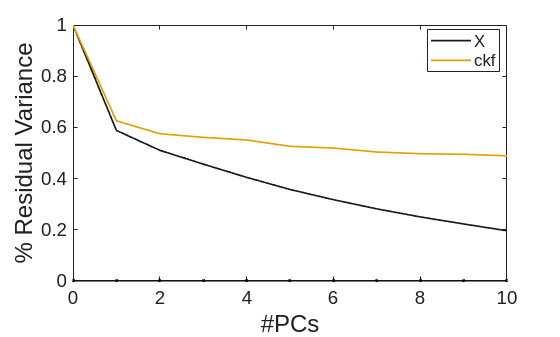

varPca(X_unfold, "PCs", 1:10, "Preprocessing", 0, "PlotCkf", true);

model.lvs=1:2;
model = pcaEig(X_unfold,'PCs',model.lvs);
model.var = trace(X_unfold'*X_unfold);

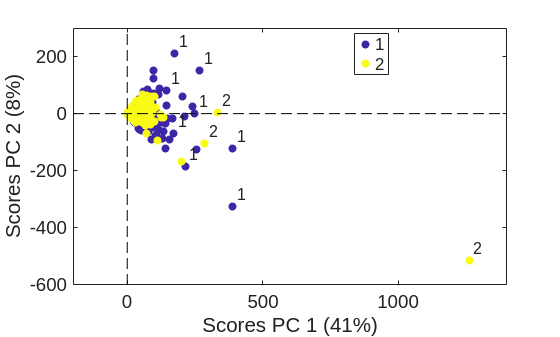

F_subject = string(F_subject);
classification = F_operations;
scores(model, "ObsLabel", classification, "ObsClass", classification, "Color", "parula");

% legend("off");

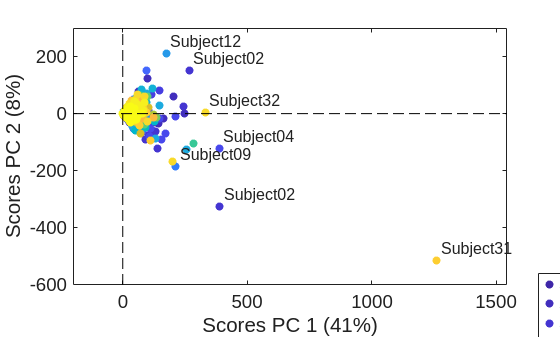

F_subject = string(F_subject);
classification = F_subject;
scores(model, "ObsLabel", classification, "ObsClass", classification, "Color", "parula");

legend('off')

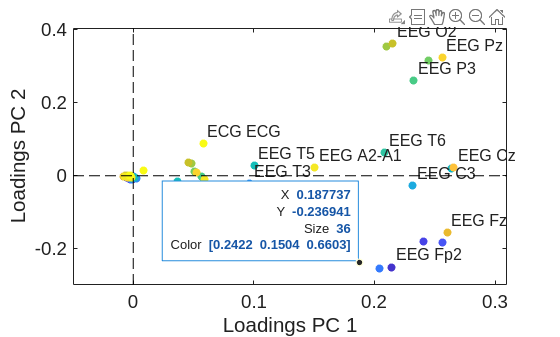

channels = string(channels);
classification = channels;

loadings(model, "VarsLabel", channels, "VarsClass", channels, "Color", "parula");
legend("off")

# MSPC - baseline vs. arithmetic

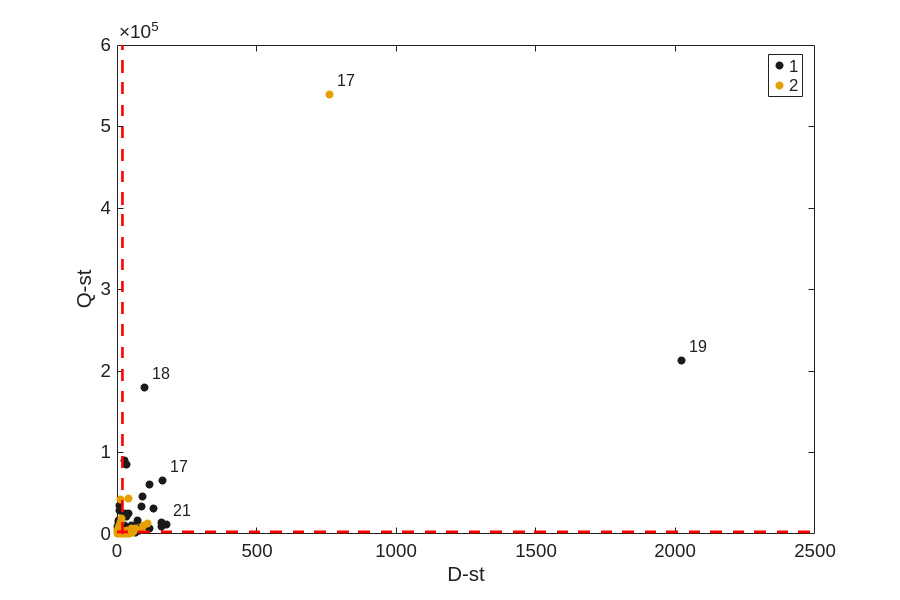

subset = 1:4:size(X_unfold, 1);
aux = X_unfold(subset, :);

test = F_operations(subset);

id_baseline = find(test == 1);
id_arithmetic = find(test == 2);

aux_baseline = aux(id_baseline, :);
aux_arithmetic = aux(id_arithmetic, :);

labels = F_ages(subset);

[Dst,Qst,Dstt,Qstt] = mspcPca(aux_baseline, 'PCs', 1:1, 'Preprocessing', 0, 'ObsTest', aux_arithmetic, ...
    'ObsLabel', labels([id_baseline, id_arithmetic]), 'LimType', 1);
f = gcf;
f.Position = [100, 100, 900, 600];


[val, idx] = max(Dstt);
idx

idx = 1625

# ASCA

F_genders_id(F_genders=="M")=1;
F_genders_id(F_genders=="F")=2;
F_subject_id = double(categorical(F_subject));
F = [F_subject_id; F_ages; F_genders_id; F_rec_years; F_quality; F_operations; F_n_subtractions];

% k = 500;
% [u,s,idk] = svds(X_unfold, k);
% X_recon = u*s;

% [T, parglmo] = parglm(X_recon, double(F)', 'Preprocessing',0, 'Ordinal', [0 0 0 0 0 0 1], 'Model', 'linear');

subset = 1:4:size(X_unfold, 1);
X = X_unfold(subset, :);
F = F(:,subset);
[T, parglmo] = parglm(X, double(F)', 'Preprocessing',0, 'Ordinal', [0 0 0 0 0 0 0], 'Model', 'linear');

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


ascao = asca(parglmo);

T.Source(2) = {'F1: Subject'};
T.Source(3) = {'F2: Age'};
T.Source(4) = {'F3: Gender'};
T.Source(5) = {'F4: Year'};
T.Source(6) = {'F5: Quality'};
T.Source(7) = {'F6: Operation'};
T.Source(8) = {'F7: n_subtractions'};
T

T = 10×7 table
            Source              SumSq       PercSumSq     df        MeanSq        F        Pvalue 
    ______________________    __________    _________    _____    __________    ______    ________

    {'Mean'              }             0           0         0           NaN       NaN         NaN
    {'F1: Subject'       }    8.9936e+05      9.9294        35         25696     86.74    0.000999
    {'F2: Age'           }    1.0014e+06      11.056         8    1.2517e+05    422.53    0.000999
    {'F3: Gender'        }     1.296e+05      1.4309         1     1.296e+05    437.49    0.000999
    {'F4: Year'          }    1.2586e+05      1.3895         2         62928    212.42     0.24376
    {'F5: Quality'       }    8.0309e+05      8.8665 

save EEG_asca T ascao 

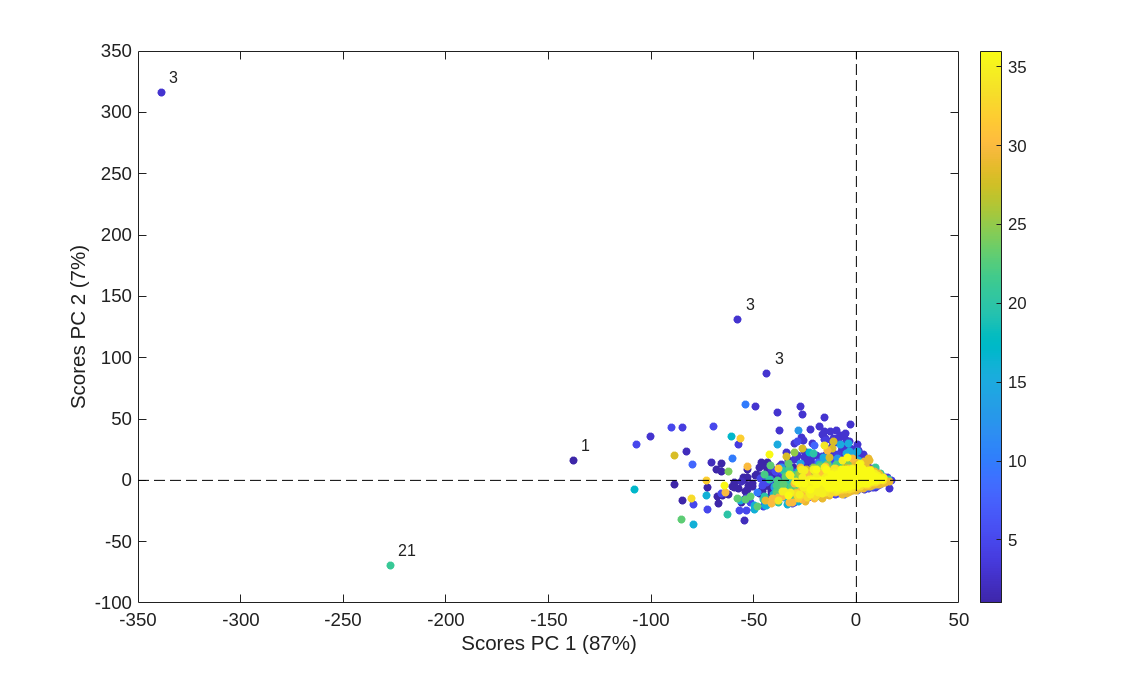

modified_ascao = ascao;
factor_id = 1;

modified_ascao.factors{factor_id}.lvs=1:2;
[~, idx] = sort(F(factor_id,:));
classification = F(factor_id, idx);

modified_ascao.factors{factor_id}.scoresV = modified_ascao.factors{factor_id}.scoresV(idx, :);
scores(modified_ascao.factors{factor_id}, "ObsLabel", classification, "ObsClass", classification, "Color", "parula" );
set(gcf,'units','normalized','outerposition',[0 0 1 2]);